**This code is about stellar motion to calculate the red shift of stars**

first The star spectrum data in the `spectra` matrix was collected at evenly spaced wavelengths (*λ*), and you are given the starting wavelength (*λ**start*), the spacing (*λ**delta*), and the number of observations.

load starData
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02

lambdaStart = 630.0200

lambdaDelta = 0.14

lambdaDelta = 0.1400

we can calculate `lambdaEnd` with the expression *λ**start*(*nObs*−1)*λ**delta, we *Use `lambdaEnd` to create a vector named `lambda` (*λ*) that contains the wavelengths in the spectrum, from *λ**start* to *λ**end*, in steps of *λ**delta*.

lambdaEnd = lambdaStart + (nObs-1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart:lambdaDelta:lambdaEnd)

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


Each column of `spectra` is the spectrum of a different star, this gives the sixth column.

s = spectra(:,6)

s = 1.0e-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


we Plot the spectra (`s`) as a function of wavelength (`lambda`). Use point markers (`.`) and a solid line (`-`) to connect the points.

Add the *x*-label `"Wavelength"` and the *y*-label `"Intensity"` to the plot.

plot(lambda,s,".-")
xlabel("Wavelength")
ylabel("Intensity")

we Create two variables, `sHa` and `idx`, that contain the minimum value of `s` and the index of that minimum value.

we Find the wavelength of the hydrogen-alpha line by using `idx` to index into `lambda, `we Store the result as `lambdaHa` (*λ**Ha*).

[sHa,idx] = min(s)

sHa = 9.8010e-14

idx = 191

lambdaHa = lambda(idx)

lambdaHa = 656.6200

we Add a point to the existing axes by plotting x = `lambdaHa`, y = `sHa` as a red square (`"rs"`) with a marker size (`MarkerSize`) of `8`.

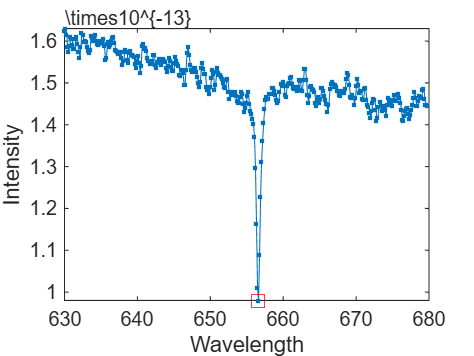

hold on
plot(lambdaHa,sHa,"rs",MarkerSize=8)
hold off

If you zoom in on the plot, you can see that the wavelength of the hydrogen-alpha line of HD 94028 is 656.62 nm, which is slightly longer than the laboratory value of 656.28 nm.

Using the hydrogen-alpha wavelength of the star, you can calculate the *redshift factor* (the speed of the star relative to Earth) using the formula *z*=(*λ**Ha*/656.28)−1. You can then calculate the speed by multiplying the redshift factor (*z*) by the speed of light (299792.458 km/s).

z = lambdaHa/656.28 - 1S

z = 5.1807e-04

speed = z*299792.458

speed = 155.3139